# EFMouse: 4x1 montage

EFMouse is a Matlab tool for electric field modelling in the mouse brain.

This notebook reproduces results for the 4x1 montage in: 

Sanchez-Romero R., Akyuz, S., & Krekelberg, B. (2024). EFMouse: a Matlab toolbox to model electric fields in the mouse brain. bioRxiv. https://doi.org/10.1101/2024.07.25.605227

The notebook is also an introductory tutorial to simulate other montages.

*(Developed by Ruben Sanchez-Romero and Bart Krekelberg,*

*Rutgers-Newark, Center for Molecular and Behavioral Neuroscience,*

*for support open an issue in https://github.com/klabhub/EFMouse/issues)*

## Introduction

EFMouse combines several elements from previous work: 

- Anatomical data from the Digimouse project.

- A refined finite element mesh of the Digimouse by Alekseichuk et al., (2019), *Neuroimage*. 

- Matlab code and inspiration from the ROAST toolbox.

- The getDP finite element method (FEM) solver (v 3.2.0).

- The Allen mouse brain atlas.

Key new functionality includes: 

- Positioning electrodes in arbitrary locations in and on the mouse body.

- Modeling craniotomies in the mouse skull.

- Analyzing the electric field in user-defined regions of interest

- Analyzing the electric field in brain regions defined in the Allen mouse atlas.

- A measure of relative focality of the electric field.

- A measure of direction homogeneity of the electric field.

For details see Sanchez-Romero et al., (2024) and *EFMouse.m* Matlab code.

## Typical workflow

The typical workflow to generate a model consists of several stages

- Stage.INIT           : Initialize. 

- Stage.MESH       : Define elecrodes and (optionally) a craniotomy.

- Stage.EXPORT   : Export files for the FEM solver getDP.

- Stage.GETDP     : Run the FEM solver.

- Stage.ATLAS      : Map the results to the Allen mouse atlas.

### Stage INIT: Initialize

We start by setting up the basic parameters of the `EFMouse` object:

o = EFMouse; % Create a default empty object of the class EFMouse
o.dir = fullfile(tempdir,"efmouse"); % Results and the object (4x1.mat) will be saved here.
o.ID = '4x1';  % A name/tag for this simulation.
o.log  = true;  % Create a log file.

Note: The log file is created but doesn't update when running a simulation from a notebook (like here). It will properly update when running EFMouse directly from the Matlab command line.

`initialize()` creates the folder to store the results. With `overwrite=true`, anything in this folder will be deleted.

o.initialize(overwrite=true); 

The initialized `EFMouse` o

Object contains the default mouse mesh (without stimulation electrodes). Let's visualize it.

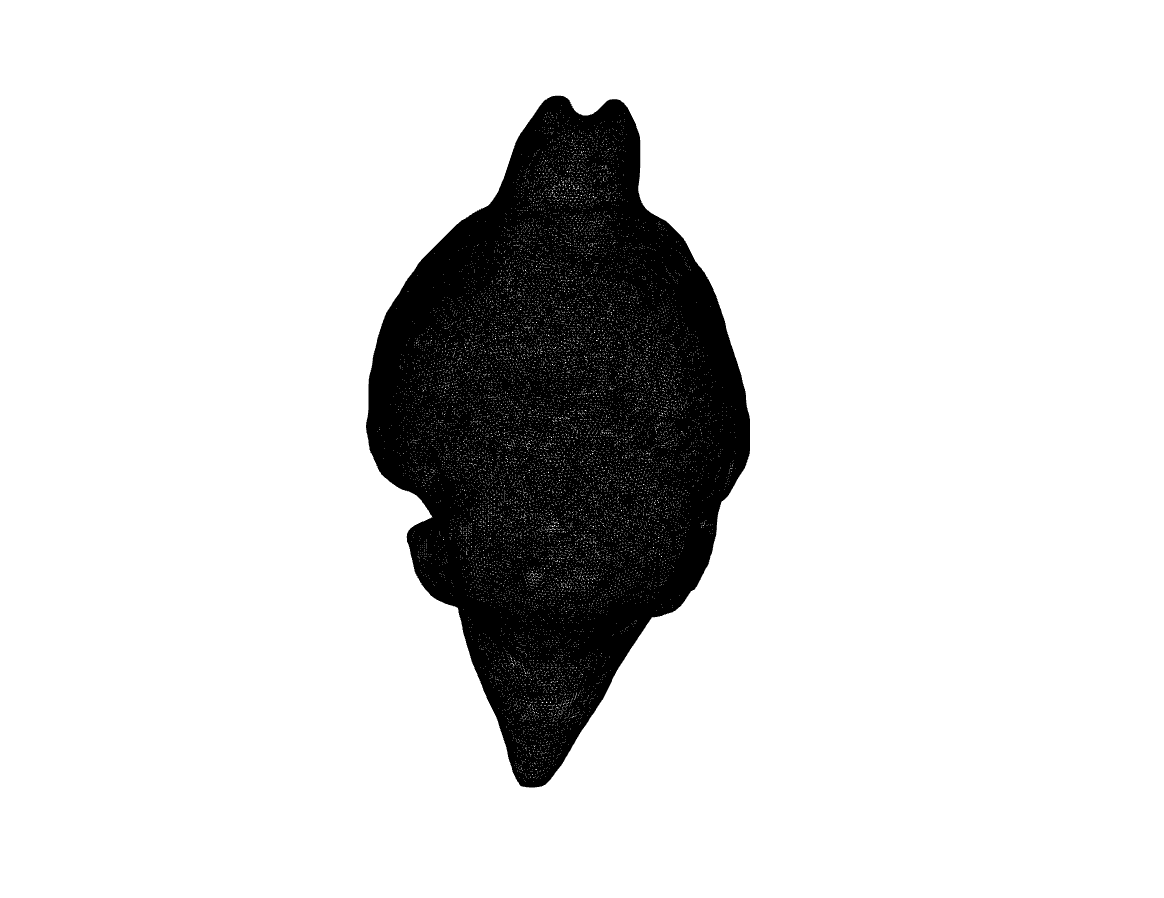

plotMesh(o,tissue="gray")

The mesh is pretty dense, so it may look like a black blob. The olfactory bulbs are visible on the top. In a regular figure window, you can use the Matlab figure tools to rotate or zoom. (You can also adapt the `plotMesh()` function in *EFMouse.m* to modifiy the figure directly.)

### Stage MESH: Create electrodes and a craniotomy

Now we define a 4x1 center-surround stimulation montage, targeting visual areas.  The surface type is an electrode that is placed on top of the animal (simulating how gel would be placed on the skin).

o.addElectrode(tag = "Anterior",current = 0.05,type="surface",shape="circle",center= [-3.5,30,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Posterior",current = 0.05,type="surface",shape="circle",center= [-3.5,25,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Lateral",current = 0.05,type="surface",shape="circle",center= [-6,27.5,4],radius=0.6, thickness=1);
o.addElectrode(tag = "Medial",current = 0.05,type="surface",shape="circle",center= [-1,27.5,6],radius=0.6, thickness=1);
o.addElectrode(tag = "Center",current = -0.2,type="surface",shape="circle",center= [-3.5,27.5,6],radius=0.6, thickness=1);

To update the model with the electrodes, we run the pipeline to Stage.MESH. With `show=true`, this also opens a figure for inspection of the mesh:

Compute stage MESH
EF Mouse Model (label: 4x1) in directory /private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse (stage=INIT).
-Meshing 5 electrodes-
Closest skin node is 0.7 away from the Anterior electrode target position.
Closest skin node is 0.1 away from the Posterior electrode target position.
Closest skin node is 0.6 away from the Lateral electrode target position.
Closest skin node is 0.3 away from the Medial electrode target position.
Closest skin node is 0.4 away from the Center electrode target position.


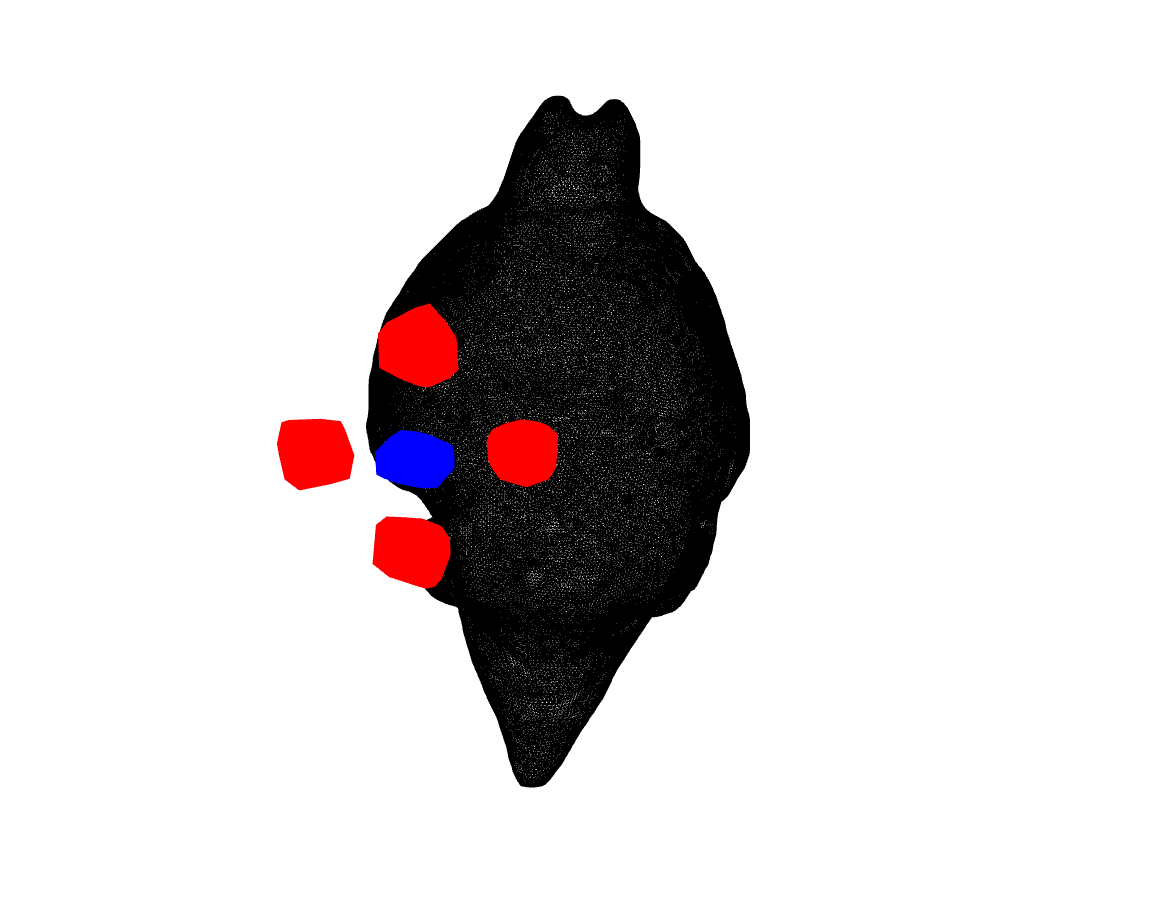

Stage MESH complete - 25.1618 seconds 


o.run(targetStage=Stage.MESH,show=true)

This mesh shows the electrodes in red (anode) and blue (cathode).

### Stage EXPORT: export the mesh and model

Up until this stage, all changes were internal to the Matlab object (saved in 4*x1.mat*), now we export files that the FEM solver getDP can read. The *.msh* file contains information on the mesh (all the nodes, elements, labels and boundaries), and the *.pro* file tells getDP which partial differential equations (PDE) model it needs to solve in this mesh.

o.run(targetStage=Stage.EXPORT)

Compute stage EXPORT
----Starting saveMesh...29-May-2025 20:42:49
----saveMesh elapsed time: 28.6688 seconds

----Starting savePro...29-May-2025 20:43:17
----savePro elapsed time: 0.0569 seconds

Stage EXPORT complete - 21.3804 seconds 


For troubleshooting, have a look at the *.pro* file in the project folder; it contains all the model specifications, including conductivity (in siemens per meter S/m) for the different tissues/elements.

type(file(o,"PRO"))

/* 
 .pro file created by EFMouse on 29-May-2025 20:43:17 
 ID: 4x1 
 Dir: /private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse 
 */

Group {

gray = Region[1];
csf = Region[2];
bone = Region[3];
skin = Region[4];
eye = Region[5];
Anterior = Region[6];
Posterior = Region[7];
Lateral = Region[8];
Medial = Region[9];
Center = Region[10];
boundaryAnterior = Region[11];
boundaryPosterior = Region[12];
boundaryLateral = Region[13];
boundaryMedial = Region[14];
boundaryCenter = Region[15];
DomainC = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,Lateral,Medial,Center}];
AllDomain = Region[{gray,csf,bone,skin,eye,Anterior,Posterior,Lateral,Medial,Center,boundaryAnterior,boundaryPosterior,boundaryLateral,boundaryMedial,boundaryCenter}];
}

Function {

sigma[gray] = 0.275;
sigma[csf] = 1.654;
sigma[bone] = 0.01;
sigma[skin] = 0.465;
sigma[eye] = 0.5;
sigma[Anterior] = 0.3;
sigma[Posterior] = 0.3;
sigma[Lateral] = 0.3;
sigma[Medial] = 0.3;
sigma[Center] = 0.3;
du_dnAnterior[] = 17

This file can be opened in the getDP gui to run it manually, but Stage.GETDP runs it for you.

### Stage GETDP: run getDP

It will take getDP between 15 and 30 minutes to compute the solutions of the Laplace equation (on 2024 Mac or Windows hardware). The results are saved in *_e.pos* and *_v.pos* files (in getDP format). In the object the results are saved as .field and .voltage.

o.run(targetStage=Stage.GETDP,show=false);

Compute stage GETDP
Info    : Running '/Users/rubensanchez/Desktop/roast/EFmouse_class/EFMouse/lib/getdp-3.2.0/bin/getdpMac /private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1.pro -solve EleSta_v -msh /private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1.msh -pos Map' [GetDP 3.2.0, 1 node, max. 1 thread]
Info    : Started (Thu May 29 20:43:59 2025, Wall = 0.138386s, CPU = 0.026933s, Mem = 5.375Mb)
Info    : Initializing Gmsh
□□Error   : Unknown number option 'General.NativeFileChooser'□
Info    : Loading problem definition '/private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1.pro'
Info    : Selected Resolution 'EleSta_v'
Info    : Loading Geometric data '/private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1.msh'
Info    : System 'Sys_Ele' : Real
□P r e - P r o c e s s i n g . . .□
Info    : Treatment Formulation 'Electrostatics_v'
  0%    : Pre-processing                                          
 10%    : 

Use the `plotEf()` function to visualize the electric field in the X direction, and then the electric field magnitude.

----Starting plotEf...29-May-2025 21:20:43


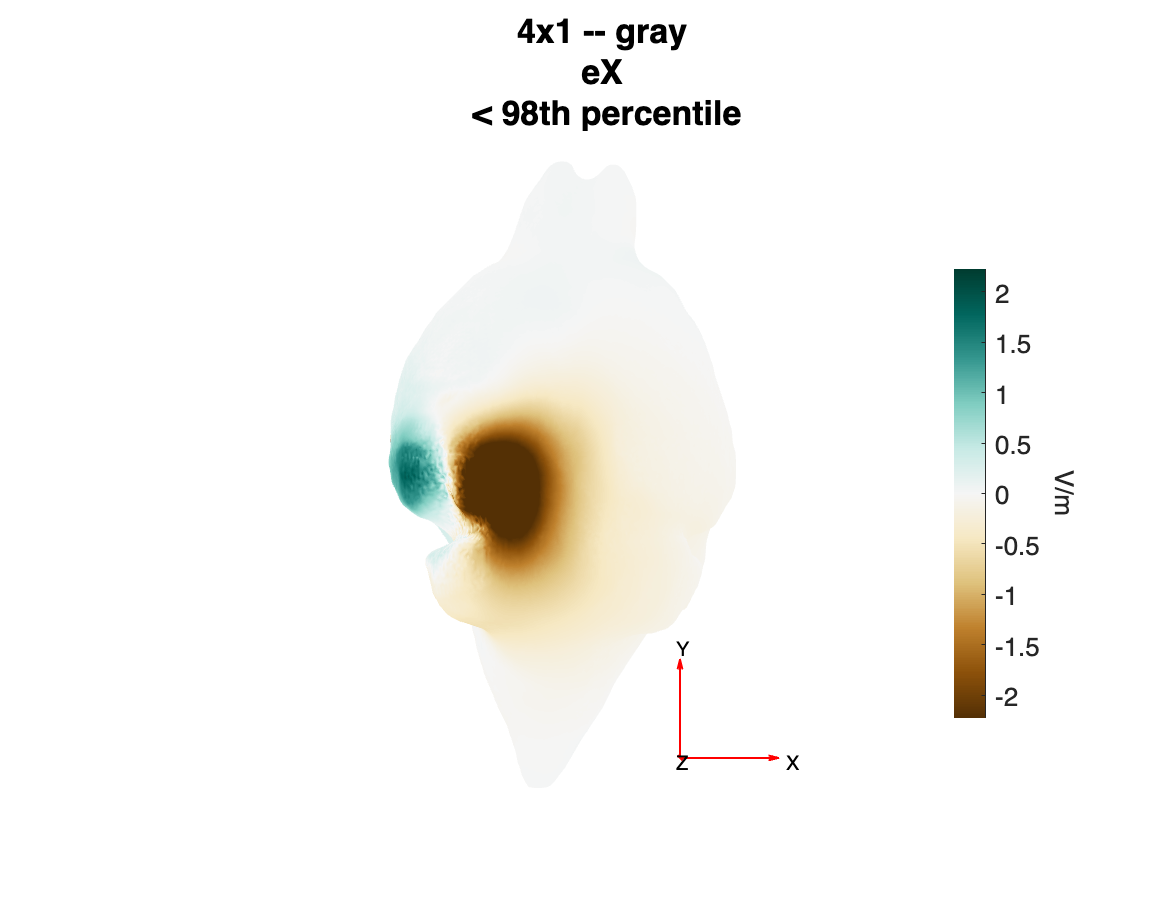

----plotEf elapsed time: 3.8662 seconds


plotEf(o,type='eX',percentile=98, tissue='gray');

----Starting plotEf...29-May-2025 21:20:47


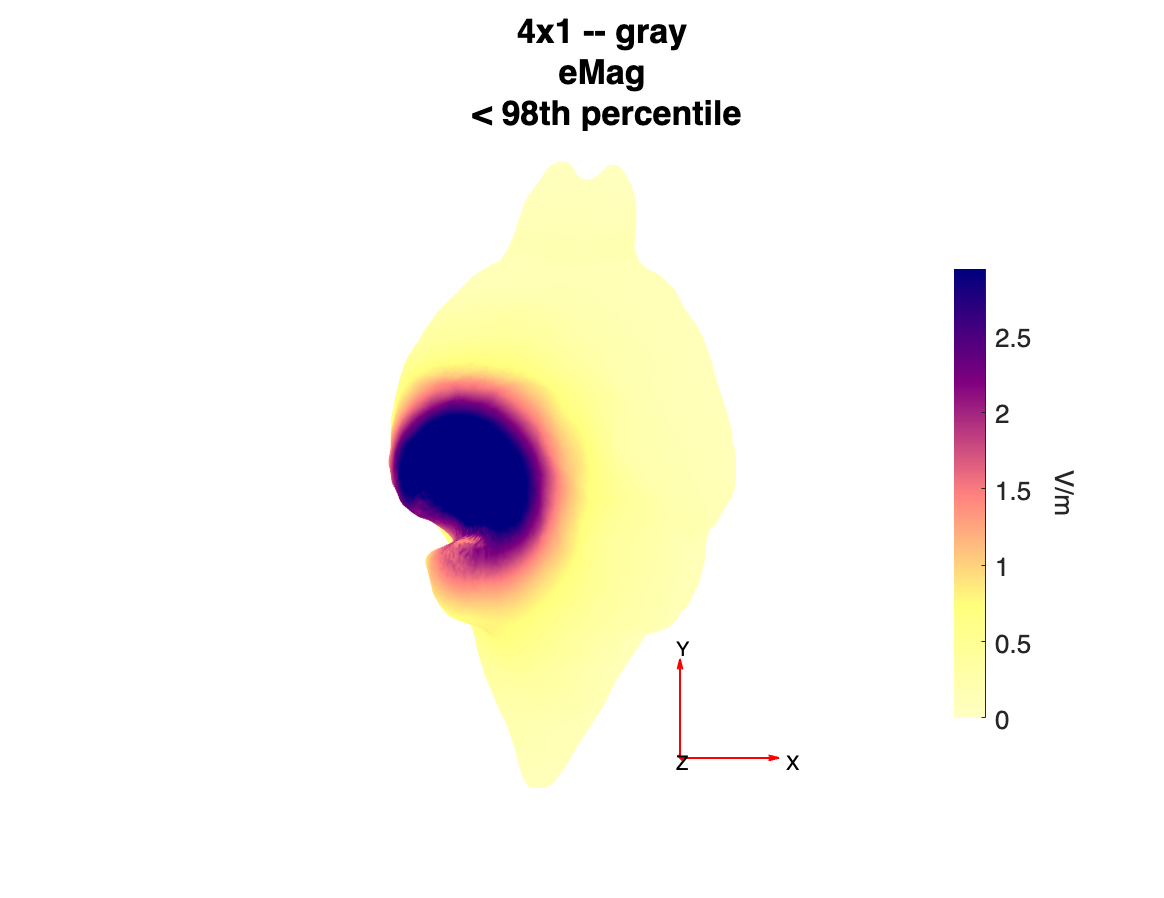

----plotEf elapsed time: 2.4787 seconds


plotEf(o,type='eMag',percentile=98,tissue='gray')

### **Tissue Based Analysis**

In general, we focus on the brain, but if necessary, we can compute electric field estimates for the rest of the mouse body for a full characterization of the anatomical effects of the electrical stimulation protocol.

See Sanchez-Romero et al., (2024) for a full description of the electric field metrics.

analyzeTissue(o,["skin" "gray"])

----Starting analyzeTissue...29-May-2025 21:21:07
Electric field summary statistics for skin tissue
               mean         median        std         min        max  
            __________    ___________    ______    _________    ______

    eX       -0.011945     7.6457e-06    2.3153       -158.9    107.16
    eY      -0.0063382    -2.4693e-07    1.8954      -149.63     151.3
    eZ        0.080097     9.4058e-05     3.239      -65.915    247.47
    eMag        0.3283      0.0017612    4.3981    3.296e-08    274.42

[Homogeneity ranges from 0 to 1]
Homogeneity = 0.4601, for ef_norm_mean: (0.227 -0.041 0.398)

Electric field summary statistics for gray tissue
              mean       median        std

### ROI Analysis

Now that we have the field estimates for each node in the mesh, we can do an ROI based analysis. For instance, a box ROI.

For the relative focality, the reference area is the rest of the gray tissue. 

See Sanchez-Romero et al.(2014), for definitions of relative focality and homogeneity.

roi.shape = 'box';
roi.center = [-3.5 27.5 3.5];
roi.width = 2;  %Left/right
roi.length = 2; % Anterior/Posterior
roi.thickness =1;  % Z
summary = analyzeRoi(o,roi,plot=true,foc_percentile_max=99.9,foc_threshold=75); % Define values for relative focality metric.

----Starting analyzeRoi...29-May-2025 21:24:20
Electric field summary statistics for a box roi in gray
              mean       median       std        min       max  
            ________    ________    _______    _______    ______

    eX       0.31857     0.31386    0.72408    -1.5151    1.9121
    eY      -0.33103    -0.38283    0.62611    -2.1037    1.3668
    eZ        2.3046      2.1785    0.58995     1.1986    4.5109
    eMag      2.5282      2.4118    0.62771     1.4428    4.5434

[Relative focality ranges from 0 to 1]
Relative focality = 0.9866, with 160508 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9304, for ef_norm_mean: (0.121 -0.129 0.913)


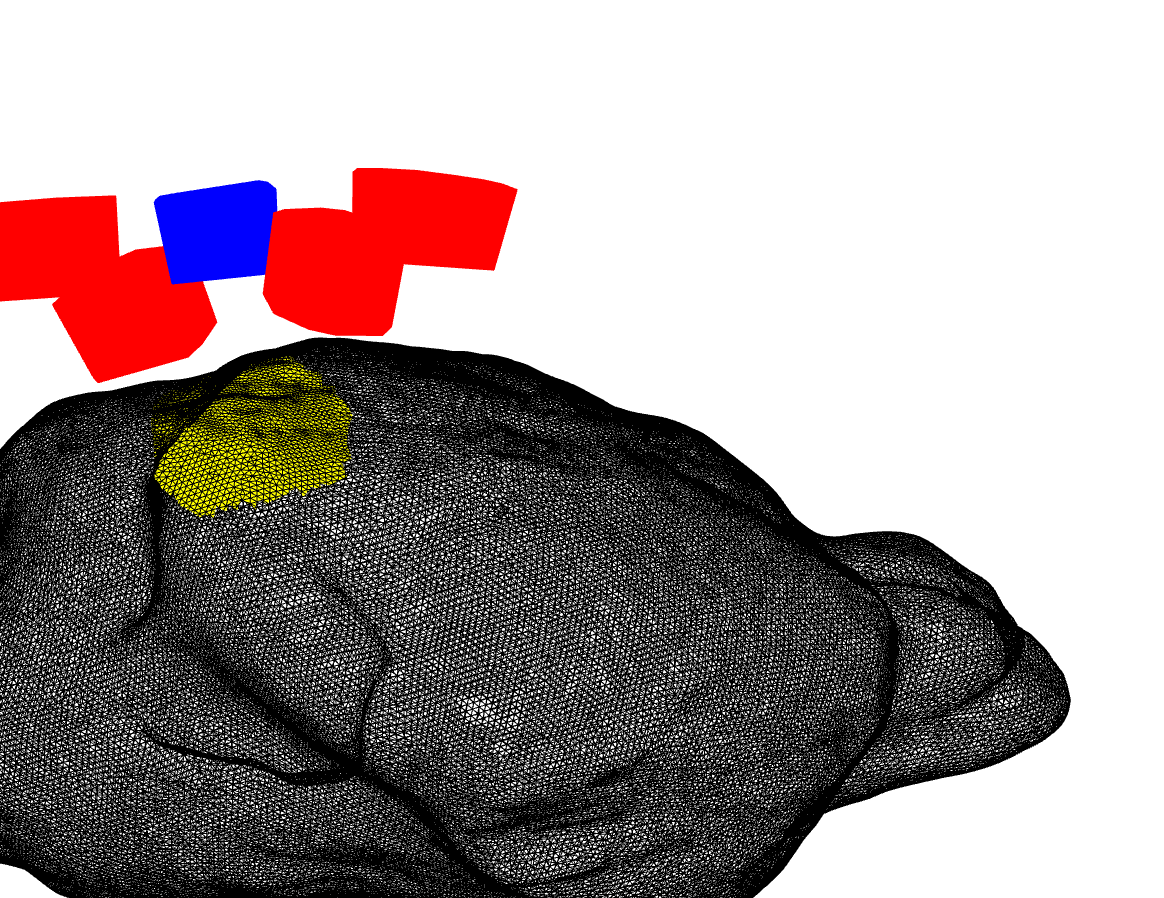

% Rotate and zoom to view the (yellow) box ROI underneath the return electrode
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

For comparison, define an analogous box ROI but in the right hemisphere

roiRight = roi;
roiRight.center(1)  =-1* roi.center(1)

roiRight = struct with fields:
        shape: 'box'
       center: [3.5000 27.5000 3.5000]
        width: 2
       length: 2
    thickness: 1


summary = analyzeRoi(o,roiRight,plot=true,foc_percentile_max=99.9,foc_threshold=75);

----Starting analyzeRoi...29-May-2025 21:24:28
Electric field summary statistics for a box roi in gray
              mean       median       std          min          max   
            ________    ________    ________    _________    _________

    eX      -0.14214    -0.14212    0.041943     -0.24768    -0.042963
    eY       -0.1112    -0.11236    0.018523     -0.15984    -0.056265
    eZ      0.026262    0.029507    0.019432    -0.036034      0.07757
    eMag     0.18494     0.18212    0.039187      0.10404      0.28543

[Relative focality ranges from 0 to 1]
Relative focality = 0.4239, with 160925 reference nodes (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.9852, for ef_norm_m

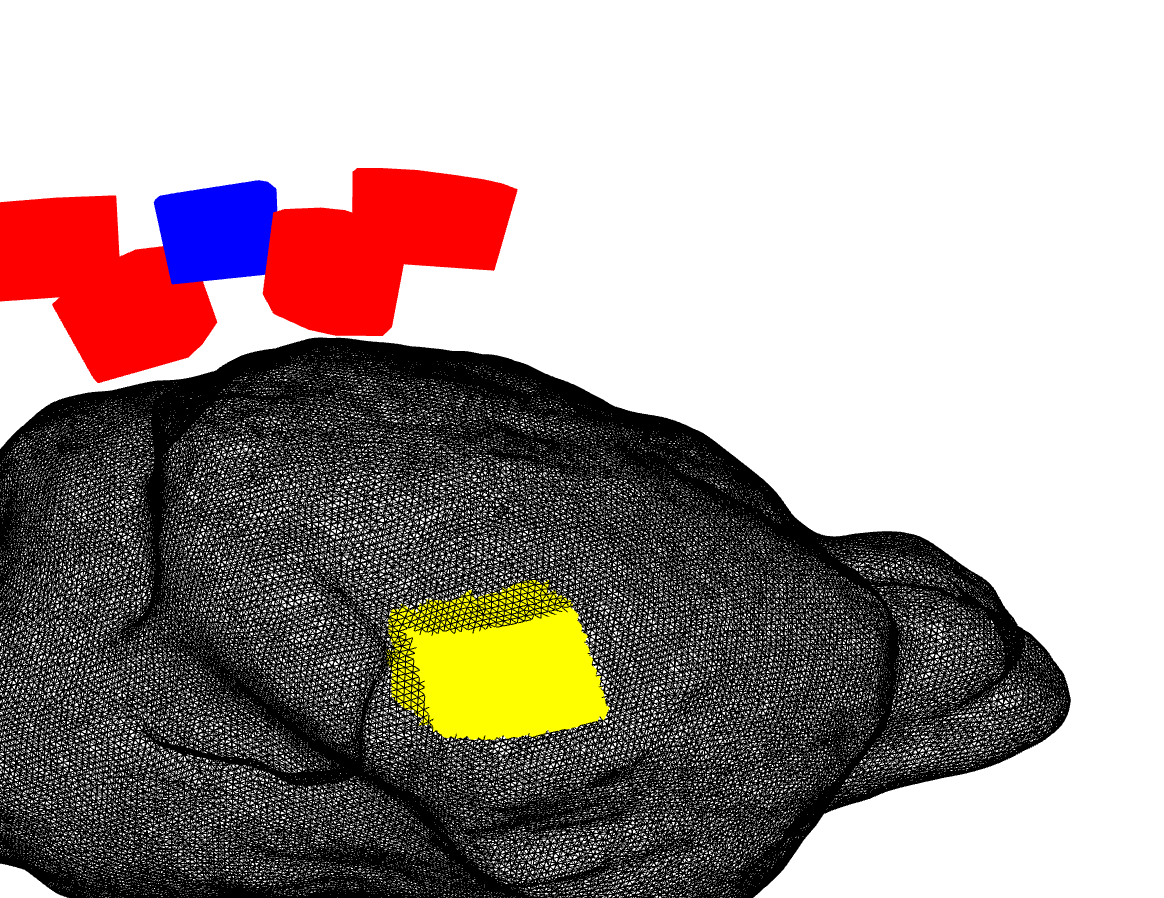

% Rotate and zoom to view the (yellow) box ROI in the right hemisphere
xlim([-3.31 1.13])
ylim([26.3 36.1])
zlim([2.31 4.98])
view([62.61 27.62])

### Stage ATLAS: Volumetric/Atlas Analysis

The mesh coordinates are not particularly intuitive, and you may want to estimate electric fields in specific brain areas (as defined in an atlas). EFMouse does this in reference to the Allen Mouse Brain Atlas. 

To use this, we first have to map the mesh-based results to the Allen Atlas. This is Stage ATLAS of the pipeline. This stage first exports the mesh-based results to a volume (using linear interpolation) and then uses the FLIRT tool in FSL to transform this volume to the coordinates of the Allen Atlas. Note that the alignment between the Digimouse mesh and the Allen Atlas is not perfect because they are based on different imaging modalities (and different mouse strains). (See Sanchez-Romero et al., (2014), for more details.) 

This will fail if FSL is not installed.

o.run(targetStage=Stage.ATLAS,startStage=Stage.ATLAS)

Compute stage ATLAS
----Starting computeVoxelSpace...29-May-2025 21:26:16
----Exporting to NIFTI volumes 
---/private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1_efm.nii.gz created
---/private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1_efX.nii.gz created
---/private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1_efY.nii.gz created
---/private/var/folders/_1/k1bbn2v52wzgtmtlcq9yg1wr0000gn/T/efmouse/4x1_efZ.nii.gz created
----computeVoxelSpace elapsed time: 35.2846 seconds
Stage ATLAS complete - 56.3963 seconds 


### Atlas Based Analysis

Once stage ATLAS has completed we can query electric fields based on a region that is defined in the Allen Atlas. For instance: 'Visual areas' for the left hemisphere.

For the relative focality the reference area is the rest of the Allen atlas "Isocortex".

T = analyzeAtlas(o,"Visual areas",hemisphere="left",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...29-May-2025 21:28:53
Area: Visual areas (1.0% of brain) , hemisphere left 
              mean       median      std         min         max  
            ________    ________    ______    __________    ______

    eX       -1.7202     -1.9887    1.3311       -4.4274    1.4344
    eY      -0.36229    -0.33139    1.0561       -3.3212    2.1406
    eZ        2.5716      2.5445     1.227    0.00066527    5.8689
    eMag      3.5418      3.5872    1.2559     0.0013876    6.5304

[Relative focality ranges from 0 to 1]
Relative focality = 0.9993, with 92410 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.8617, for ef_norm_mean: (-0.473 -0.098 0.71

For comparison, we can query results for the right hemisphere, which is contra-lateral from the targeted area.

T = analyzeAtlas(o,"Visual areas",hemisphere="right",foc_threshold=75,foc_percentile_max=99.9,foc_reference='Isocortex');

----Starting analyzeAtlas...29-May-2025 21:28:55
Area: Visual areas (1.0% of brain) , hemisphere right 
              mean         median        std          min          max   
            _________    __________    ________    __________    ________

    eX        -0.2196      -0.22349      0.1167      -0.48481           0
    eY       -0.13506      -0.13923    0.065983      -0.30262           0
    eZ      -0.028144    -0.0042198    0.075726      -0.29784    0.095572
    eMag        0.268       0.26794     0.13878    0.00026594     0.60635

[Relative focality ranges from 0 to 1]
Relative focality = 0.6460, with 92457 reference voxels (cutoff: eMag > 75.00% of the target area max (99.90th percentile))
[Homogeneity ranges from 0 to 1]
Homogeneity = 0.

## Tips and Tricks

- The run function can be called with any `targetStage` from Stage.INIT to Stage.ATLAS. Stages that have already been completed will not be run again, and all stages that need to be completed to reach the `targetStage` will be completed in turn.

- IMPORTANT: To continue working with a model from a previous Matlab session, you create an `EFMouse` object with the `dir` and `ID` input arguments to specify the folder with the (previously saved) results and the ID of the montage. For instance, to open the simulation from the tutorial at the stage where it was last saved:

o = EFMouse(dir=tempdir,ID='4x1')